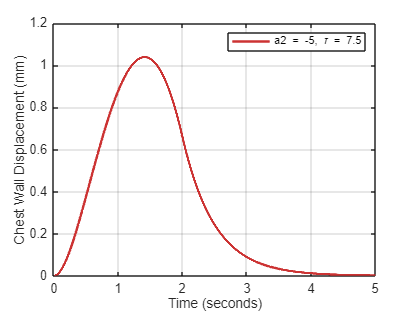

% Based on Singh et al. (2020) 
%All parameters have either been manually adjusted or taken out of Singh et
% al. (2020).

fs = 1000;              % Sampling frequency(Hz)
t1 = 2;                 %Inhale duration(s)
t2 = 3;                 %exhale duration(s)
t_cycle = t1 +t2;      %Total cycle duration (4-5s) [5]
t = 0:1/fs:t_cycle;     % Time vector for the full cycle

a2 = -5;                %Inhale shaping parameter (RANGE -1 to -7)
a1 = 10;                % pressure coefficient (calibrated for peak)
a0 = 0;                 % Starting pressure
tau_rs = 0.5;           %system time constant
Rrs = 2;                %respiratory resistance
tau = 7.5;              % Exhale shaping parameter (RANGE 3.5 to 7.5)
V0 = 0;                 % Initial volume/distance

%coefficients for Inhalation
A1 = a2;
A2 = a1 - 2*a2*tau_rs;
A3 = a0 - a1*tau_rs + 2*a2*tau_rs^2;

% Inhalation Phase
idx_inhale = t <= t1;
ti = t(idx_inhale);
V_inhale = (tau_rs/Rrs) * (A1*ti.^2 + A2*ti + A3.*(1 - exp(-ti/tau_rs))) + V0*exp(-ti/tau_rs);

%Exhalation Phase (t1 to t1+t2)
idx_exhale = t > t1;
te = t(idx_exhale);
P_t1 = a2*t1^2 + a1*t1 + a0;  %pressure at end of inhalation
V_t1 = V_inhale(end);         %Volume at end of inhalation

V_exhale = (P_t1 / (Rrs * (1/tau_rs - 1/tau))) *(exp(-(te-t1)/tau) - exp(-(te-t1)/tau_rs)) + V_t1 * exp(-(te-t1)/tau_rs);

V_total = [V_inhale, V_exhale];

figure;
plot(t, V_total, 'LineWidth', 2, 'Color', [0.8 0.2 0.2]);
grid on;
title('');
xlabel('Time (seconds)');
ylabel('Chest Wall Displacement (mm)');
legend(['a2 = ', num2str(a2), ', \tau = ', num2str(tau)]);